# Code 1: Monte-Carlo Simulation of Solar Wind Uncertainty and its Effect on Polar Cap Potential Saturation

by Nithin Sivadas

**Note: Please do not share without Nithin's explicit permission. **

**Being edited before finalizing**

Update: 7th October 2021; 27th Sep 2021; 20th Aug 2021; 4th July 2021; 

29th Dec 2021 - Corrected the kan-lee formula

21st July 2025 - Including calculated "other uncertainties" from [Michotte de Welle et al. 2024](https://doi.org/10.1029/2023JA032098) (See Code3_Calculating_magnitude_uncertainty.ipynb) 

## Introduction

The cross polar cap potential saturates at strong solar wind forcing. In particular, the combined polar cap index (PCI = 0.5*(PCN+PCS)) - which is proportional to the cross-polar cap electric field, which also appears to be linearly related to the polar cap potential, saturates at high values of the solar wind "merging" electric field ($E_m$). There are at least 10 models that attempts to explain this non-linear relationship. All of these models propose a physical mechanism that reduces the day-side reconnection rate or the potential in the ionosphere, for a given solar wind driving ([Borovsky 2009, Table A1](http://doi.wiley.com/10.1029/2009JA014058)). However, we propose an alternate explanation: the uncertainty in solar wind measurements. In other words, the merging electric field is an uncertain estimate of the true driver - which is flow within the magnetosheath on open magnetic field-lines from the polar cap.

Through this code, we demonstrate that the saturation of the polar cap potential is a result of **our uncertainty** in 

- the propagation delay of solar wind from L1 to the bow shock, 

- the propagation of the day-side electric field from the magnetopause to the polar cap ionosphere

- the random variation in the magnitude of the solar wind electric field as it propagates from L1 into the magnetosheath, and transmitted down to the polar cap (magnitude uncertainty)

The propagation delay of the effect of the solar wind forcing from L1, all the way to the polar cap ionosphere, is stochastic. And as a result, there is a small but random error in our best estimates of the propagation delay. Additionally, there is a random (zero-mean) variability in the magnitude of the solar wind geoeffective field as it propagates to the ionosphere due to physical processes in the magnetosheath, which result in additional uncertainty in our best estimates of the geoeffective field mapped to the polar cap. The uncertainty in our estimate of the geoeffective field time-shifted to the polar cap, varies with the magnitude of the field. Combining this property with the fact that the underlying probability distribution of the geoeffective field is a log-normal distribution, results in a biased estimate of the true solar wind driver which actually drives the polar cap electric field.

In the following code, we develop a stochastic model (a monte-carlo simulation) of the relationship between our estimate of the solar wind merging electric field (${E^* }_m$ $\sim$ $X^*$) and its hypothetical true value ($X$). There is reason to believe that mapping the geoeffective field accurately to the polar cap leads to the combined polar cap index ($i\ldotp e\ldotp ,\;X\proptoY_{\textrm{PC}} =\;\textrm{PCI}$) (Stauning 2012), as electric field along the open field-lines from the polar cap, ought to be transmitted without attenuation along the field line, as MHD theory holds true since there is no resistance parallel to the field line. We use this assumption only to infer that the underlying probability distribution and autocorrelation function of $X$ is similar to $\textrm{PCI}$. Through our error model, we show that our estimate of the solar wind merging electric field in the polar cap $X^*$**, is a biased estimate of **$X$, by making informed estimate of the stochastic nature of $X$ and our uncertainty in the propagation delay and intrinsic scatter. 

The most important result is that our bias, varies non-linearly with $X$. The reason for this non-linear bias in the estimate is primarily due to the misidentification of far more lower values of $X$ as high values.  And we find that $X$ saturates with our estimate $X^*$, in the same way as the polar cap index $\left(\textrm{PCI}\right)$ saturates with our estimate of the true shocked solar wind driver ${E^{\textrm{sh}} }_m$. Firstly, this shows that an estimate of the true solar wind driver will lead it to be exactly linear with $\textrm{PCI}$ (with a ${45}^{\circ \;}$slope), and this is consistent with the model. And if the stochastic model's relationship between $X$ and $X^*$ is true, and the uncertainties in propagation delay and the magnitude uncertainty are true, then the non-linearity between polar cap index (and hence the polar cap potential) and solar wind forcing will follow logically from it.

In other words, given our uncertainty in the solar wind driver estimated at L1, we should expect the exact statistical non-linear relationship we observe between the polar cap potential and solar wind merging electric field. Finally, we show that the same model predicts almost exactly the non-linear behavior between auroral electrojet current strength (SML) and the merging electric field. 

## Extract Data

#### Input Data Files

%Specify the folder where all the data is stored. See: https://github.com/nithinsivadas/uncertainty/tree/main/Data
DataDir = 'C:\Users\nithin\Documents\GitHub\uncertainty\Data\'; 

superMagFile = [DataDir,'20210927-20-45-supermag.txt']; 

From [SuperMag](https://supermag.jhuapl.edu/indices/?fidelity=low&layers=SME.UL&start=2001-01-30T05%3A00%3A00.000Z&step=14400&tab=download) (JHU/APL)

windDataFolder = [DataDir,'omni_components\'];

From OmniWeb [WIND Spacecraft measurement](https://spdf.gsfc.nasa.gov/pub/data/omni/high_res_omni/sc_specific/) (NASA)

polarCapDataFolder = [DataDir,'pc_index\PCI\'];

Including heteroskedastic uncertainty functions from calculated uncertainty using simultaneous magnetosheath measurements. This uncertainty was then fitted into a spline function.

load([DataDir,'uncertainty_functions.mat']);

Set this to 1, if you want to use previous run of random variables. Set this to 0, if you want to carry out a new run (which will take some more time, and make minor changes in the plots because of the statistics). 

setLoadExistingData=1;
if setLoadExistingData==1
    load([DataDir,'polar_cap_previous_run.mat']);
end

% Set this to 
% 1 if you wish to save the images onto a folder, or 
% 0 if you just would like to view it
setExportFig = 1;

From [https://pcindex.org/archive](https://pcindex.org/archive) (Arctic and Antarctic Research Institute, and the Technical University of Denmark)

#### Output Folder

%Specify the output folder where you'd like to store the images
outputFolder = 'H:\My Drive\Research\Projects\Paper 6\Draft\Version 5\Figures\Original\';

if ~setLoadExistingData
    [wind, pci, Fsml, Xm, XmTime, Fpcc, acf_fit_Xm, acf_fit_PCC, acf_fit_var]= initialize(superMagFile,windDataFolder,polarCapDataFolder);
end
% Requires
% Mapping Toolbox
% Image processing toolbox
PCC = Fpcc(datenum(XmTime));

**Defining data we use**

For solar wind geoeffective field values, we calculate that using the time-shifted WIND measurements from the OMNI2 database. 

For the polar cap potential, we use the polar cap index data set.  

Xm - The solar wind geoeffective field, derived from OMNI measurements. $X_m =E_{m\;} =\textrm{VB}\;\sin^2 \;\frac{\theta }{2}\;$, in [mV/m]

PCC - Is the combined polar cap potential, in [mV/m]. It is a measure of the geoeffective field observed in the ionosphere. 

We also estimate average autocorrelation for the above variables. 

    acf_fit_Xm - The autocorrelation function associated with the measurement Xm

    acf_fit_PCC - The autocorrelation function associated with the measurement PCI

    acf_fit_var - The autocorrelation function associated with $\textrm{var}=X_m -\textrm{PCI}\;$

## Error Model

We develop a stochastic model, 


$$X^*(t) = X(t+dt_1 + dt_2) + \epsilon(t)$$


where statistical properties of $X$ corresponds to $\textrm{PCI}$, and $X^*$ corresponds to ${E^* }_m \left(t+<{\textrm{dt}}_1 >+<{\textrm{dt}}_2 >\right)$ that is time shifted with a constant propagation delay from L1, to nose, to the ionosphere. 

How we arrived at this relationship between $X^*$ and $X$, is described in the detailed diagram below. Here, $t$ is the time of the measurement at L1. 

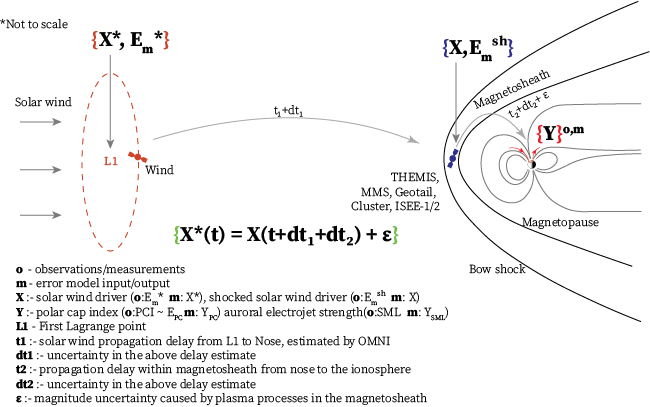

Inspired from data, we assume input distribution and ACFs for $X$. 


$$\begin{array}{l}
X\sim \textrm{Lognormal}\left(\mu \;=-0\ldotp 2518,\sigma =0\ldotp 85\right)\\
R_{\textrm{XX}} \left(\tau \;\right)\sim \textrm{from}\;\textrm{data}
\end{array}$$


We estimate the magnitude uncertainty in $X$ from a database of THEMIS, MMS, Cluster satellites within the magnetosheath that are close to the bowshock, and estimate for a given value of $E_m^{sh}$ measured at the magnetosheath the variance in the corresponding $E_m^*$ measured at L1. This appears to increase with true solar wind driver $E_m^{sh}$ uptil 12 mV/m, and then remain the same or increase, there is not enough data to say eitherway. The relative error is shown here. 


$$\begin{array}{l}
\epsilon \left(t\right)=f\left(X\left(t\right)\right)N\left(t\right)\\
N\sim \textrm{Normal}\left(\mu =0,\sigma =1\right)
\end{array}$$


Shape of $f\left(x\right)$ is determined by the uncertainty estimated from the python code that analyzes data from the magnetosheath measurements, and the function is given by bayanefit. 

We also assume an autocorrelation for the $\epsilon \left(t\right)$, inspired from the $\textrm{ACF}$ observed in the difference ${E^* }_m -\textrm{PCI}$

$\epsilon \;\left(t\right)$ corresponds to variability caused by **scattering within the magnetosheath** of shocked plasma upstream of and as it flows perpendicular to open field lines from the polar ionosphere. Sources of this scattering might be - the slowing or speeding up of the solar wind as it travels from L1 to nose, foreshock effects, plasma jets and waves in the magnetosheath and magnetopause. It is a heteroscedastic variability, i.e., the variance increases with increasing value of $X$. 

We also estimate the uncertainty in propagation delays from pervious literature.


$${\textrm{dt}}_1 ~\textrm{uncertainty}\;\textrm{in}\;\textrm{the}\;\textrm{delay}\;\textrm{from}\;\textrm{L1}\;\textrm{to}\;\textrm{magnetopause}\;\textrm{nose}\;\left(\textrm{bowshock}\right)$$



$${\textrm{dt}}_2 ~\textrm{uncertainty}\;\textrm{in}\;\textrm{the}\;\textrm{delay}\;\textrm{from}\;\textrm{magnetopause}\;\textrm{nose}\;\textrm{to}\;\textrm{polar}\;\textrm{cap}\;\textrm{ionosphere}$$


A step by step description and generation of the inputs and assumptions follow. 

## Inputs

### Probability Distribution Function of X

The underlying probability distribution function of $X$ is an input to the model. It is a lognormal distribution, chosen to match the the probability distribution of the polar cap electric field $\textrm{PCI}$. 

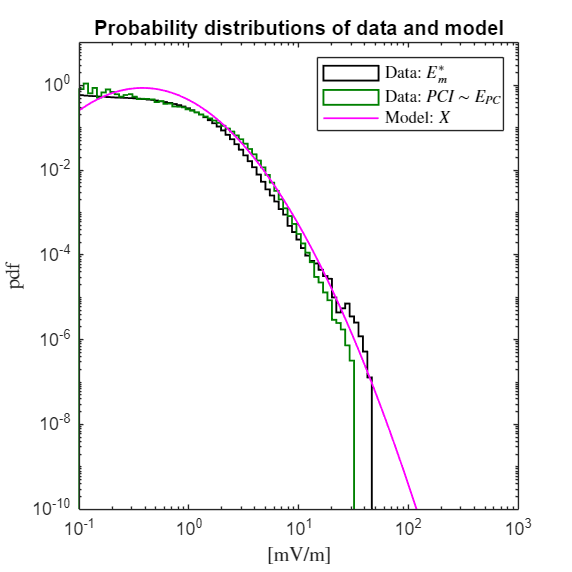

set(0,'defaulttextInterpreter','latex');
f1 = figure; 
resize_figure(f1,2*55,2*55);
XBinsLog = logspace(-1,3,100);
histogram(Xm,XBinsLog,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
hold on;
histogram(PCC,XBinsLog,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor',[0 0.5 0]);
hold on;
plot(XBinsLog,lognpdf(XBinsLog,-0.2518,0.85),'m','LineWidth',1);
set(gca,'XScale','log','YScale','log');
ylim([10^-10,10]);
legend('Data: ${E}^*_m$','Data: $PCI \sim E_{PC}$','Model: ${X}$','Interpreter','latex');
xlabel('[mV/m]');
ylabel('pdf');
title('Probability distributions of data and model','Interpreter',"none");

### Autocorrelation Function of X and $\epsilon$

The autocorrelation of the stochastic process, $X\left(t\right)$, that we are trying to model, is also an input to the model. We derive it from the autocorrelation of $\textrm{PCI}$. Similarly, the magnitude uncertainty $\epsilon \left(t\right)$ is also modelled as a stochastic process whose ACF is assumed to be the ACF of the error/variability ${E^* }_m -\textrm{PCI}$.

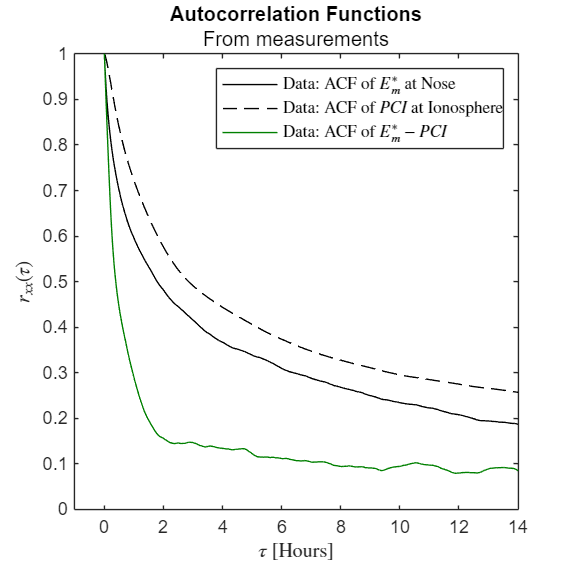

f2 = figure; 
resize_figure(f2,2*55,2*55);
tInd = 0:1000;
plot(tInd./60,acf_fit_Xm(tInd),'k');
hold on;
plot(tInd./60,acf_fit_PCC(tInd),'--k');
hold on;
plot(tInd./60,acf_fit_var(tInd),'Color',[0 0.5 0]);
legend('Data: ACF of $E^*_m$ at Nose','Data: ACF of $PCI$ at Ionosphere','Data: ACF of $E^*_m - PCI$','Interpreter','latex');
title('Autocorrelation Functions','From measurements','Interpreter',"none");
xlim([-1, 14]);
ylim([0,1]);
xlabel('$\tau$ [Hours]')
ylabel('$r_{xx}(\tau)$')


    dt = 1; % 1 min intervals
    nSamplesM = 2^12; % Upto 80 hours
    nEnsemblesM =16000;
    lag = fftshift(-nSamplesM:1:nSamplesM-1)'.*dt;
    
    % Generating auto-correlation matrices for the model
    Rm = acf_fit_PCC(abs(lag));
    RmErr = acf_fit_var(abs(lag));
    
    % Input 2 : The autocorrelation matrix/function
    RmMatrix = toeplitz(Rm(find(lag==0):find(lag==(nSamplesM-1)*dt)));
    RmErrMatrix = toeplitz(RmErr(find(lag==0):find(lag==(nSamplesM-1)*dt)));
    
 if ~setLoadExistingData
    
    % Input 1: Probability distribution 
    X = MvLogNRand(repmat(-0.2518,nSamplesM,1),repmat(0.85,nSamplesM,1),nEnsemblesM,RmMatrix); %% PCC Substitute in model
end

## Assumptions

### The different forms of variability (Figure S3,S4)

#### Propagation delay uncertainty

The solar wind geoeffective field takes time $t^{\prime }$ to propagate from L1 to Ionosphere, where $t_m$ is our estimate of the propagation time. 

$t_1$is our estaimte of the solar wind propagation from L1 to nose

$t_2$is our estimate of the propagation of disturbances from the nose to the polar cap ionosphere (usually a constant 20 minutes)

Usually, 


$$t_m =t_1 +t_2$$


Where $t_m$ is the solar wind electric field measurement time. Where $<{\textrm{dt}}_1 >$ and $<{\textrm{dt}}_2 >$ are constant delays. However, these constant delay offsets are not the real story, since these propagation delays are stochastic. 


$$t^{\prime } =t_m +{\textrm{dt}}_1 +{\;\textrm{dt}}_2$$


As a result, we assume a distribution for the propagation delay uncertainties ${\textrm{dt}}_{1\;}$and ${\textrm{dt}}_2$, using help from the literature. 

${\textrm{dt}}_{1\;} \;\sim t-\textrm{location}\;\textrm{scale}\;\textrm{distribution}\;\left(\textrm{stochastic}\;\textrm{propagation}\;\textrm{delay}\;\textrm{from}\;\textrm{L1}\;\textrm{to}\;\textrm{Nose}\right)$[(Case and Wild, 2012)](https://agupubs.onlinelibrary.wiley.com/doi/full/10.1029/2011JA016946)

${\textrm{dt}}_2 \;\sim \textrm{Weibull}\;\textrm{distribution}\;\;\left(\textrm{stochastic}\;\textrm{propagation}\;\textrm{delay}\;\textrm{from}\;\textrm{Nose}\;\textrm{to}\;\textrm{Ionosophere}\right)$ [(Stauning 2012, Section 5, Pg 369-372) ](https://www.intechopen.com/books/exploring-the-solar-wind/the-polar-cap-pc-indices-relations-to-solar-wind-and-global-disturbances)



    sigma1 = 8; %8 minutes
    sigma2 = 25; %25 minutes 
    
    
    tsubset = 100:1:nSamplesM;
    nSubsetSample = length(tsubset);  
    timeM = 1:1:nSamplesM; %% Time at Ionosphere
    
    mean1 = 0;
    mean2 = 17;
    
    shape1 = 1.3;
    shape2 = 1.3;

 if ~setLoadExistingData    
    % L1 to Nose, propagation delay uncertainty
    terr1 = (random('tlocationscale',mean1,sigma1,shape1,nSamplesM,nEnsemblesM))'; 
    
    
    % Nose to Ionosphere, propagation delay uncertainty
    terr2 = (random('Weibull',sigma2,shape2,nSamplesM,nEnsemblesM))'-mean2;

 end

    % Time delay for relationship between XI and WI
    t_WI_XI = timeM + terr1 + terr2; 




The distributions are shown in the plot below. 

**Figure ED3: Propagation delay uncertainty**

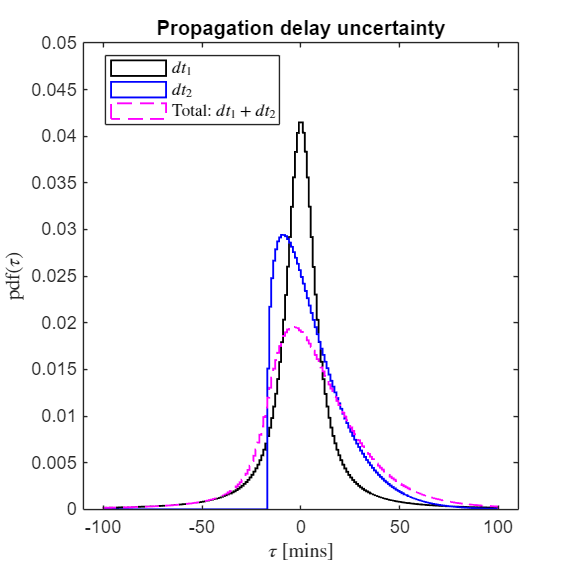

figS3 = figure; 
resize_figure(figS3,2*55,2*55);
tbins = -100:1:100;
histogram(terr1,tbins,'Normalization',"pdf",'DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
hold on;
histogram(terr2,tbins,'Normalization',"pdf",'DisplayStyle','stairs','LineWidth',1,'EdgeColor','b');
hold on;
histogram(terr2 + terr1,tbins,'Normalization',"pdf",'DisplayStyle','stairs','LineWidth',1,'EdgeColor','m','LineStyle','--');
xlabel('$\tau$ [mins]');
ylabel('pdf($\tau$)');
legend('$dt_1$','$dt_2$','Total: $dt_1 + dt_2$ ','Interpreter','latex','Location','best');
title('Propagation delay uncertainty','Interpreter',"none");
ylim([0,0.05]);
if setExportFig
export_fig([outputFolder,'FigureED3.png'], ...
    '-r600','-png','-nocrop',figS3);
export_fig([outputFolder,'FigureED3.pdf'], ...
    '-r600','-pdf','-nocrop',figS3);
end

#### Magnitude Uncertainty $\epsilon \left(t\right)$

We assume $\epsilon \left(t\right)$, to capture the random changes in the magnitude of the geoeffective field as it propagates from L1 to the ionosphere. And this scatter, is heteroscedastic in nature, i.e., it varies with the magnitude of $X$. The plot below shows the nature of this variation that we have chosen for the model. This is calculated from the variance of L1 measurements of the solar wind driver given a particular shocked solar wind driver in the magnetosheath measured using THEMIS, Cluster, and MMS satellites. Ultimately, most of the variability in the magnitude uncertainty is a result of the plasma and field processes within the magnetosheath that lead to random fluctuations in the local plasma and field conditions. 

**Figure 3d: Other uncertainty**

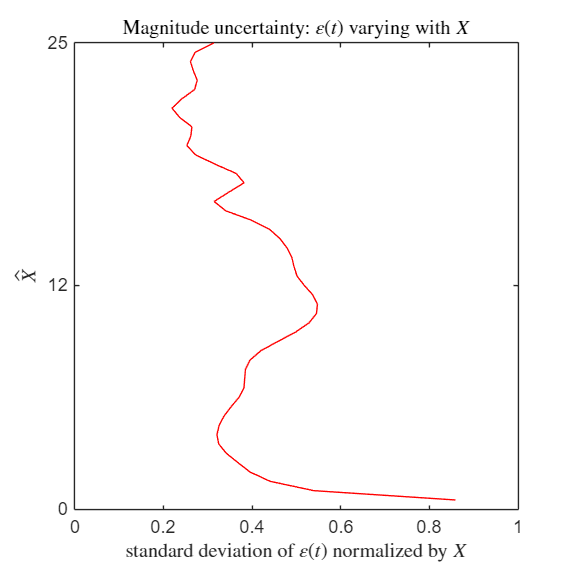

XBins = 0:0.5:25;
figS4 = figure; 
resize_figure(figS4,2*55,2*55);

plot(bayanefit(XBins')./XBins',XBins,'r');

xlim([0,1]);
ylim([0,25]);
xlabel('standard deviation of $\varepsilon(t)$ normalized by $X$');
ylabel('$\hat{X}$');
title('Magnitude uncertainty: $\varepsilon(t)$ varying with $X$','Interpreter',"latex");
set(gca,'YTick',[0,12,25]);

if setExportFig
export_fig([outputFolder,'Figure3d.png'], ...
    '-r600','-png','-nocrop',figS4);
export_fig([outputFolder,'Figure3d.pdf'], ...
    '-r600','-pdf','-nocrop',figS4);
end

 $\epsilon \left(t\right)$is set to have a normal probability distirbution, whose standard deviation is a function of X shown by the above figure, with an autocorrelation function derived from the observed autocorrelation of ${E^* }_{m\;} -\textrm{PCI}$. 

if ~setLoadExistingData
HNoise_B25 = @(X,Sigma,nEnsembles,nSamples,RmMatrix) (reshape(bayanefit(X),size(X))).*(MvNRand(repmat(0,nSamples,1),repmat(Sigma,nSamplesM,1),nEnsembles,RmMatrix));
HNoiseX_B25 = HNoise_B25(X,1,nEnsemblesM,nSamplesM,RmErrMatrix);
end

## Running the toy model

Here lies the primary equation, that represents the stochastic model developed in this work. 


$$X^*(t) = X(t+dt_1 + dt_2) + \epsilon(t)$$


These variables correspond to the following variable names in the code. 

WI ~ $X^*$

XI ~ $X$

HNoiseX ~ $\epsilon \left(t\right)$

t_WI_XI ~ $t+{\textrm{dt}}_1 \;-<{\textrm{dt}}_1 >+{\;\textrm{dt}}_2 -<{\textrm{dt}}_2 >$

WI = zeros(nEnsemblesM,nSubsetSample); % Erroneous estimate at the ionosphere
HIXB = zeros(nEnsemblesM,nSubsetSample); % Error

XI = X(:,tsubset); % True value at the ionosphere

for i=1:1:nEnsemblesM
    temp = X(i,:)'+ HNoiseX_B25(i,:)';
    temp(temp<0)=0;
    WI(i,:) = interp1(timeM',temp,t_WI_XI(i,tsubset)','nearest');
    HIXB(i,:) =interp1(timeM',HNoiseX_B25(i,:)',t_WI_XI(i,tsubset)','nearest');
end



## Output

### Estimated polar cap potential

The primary output of the model is $X^* \left(t\right)$ or "WI". This is our erroneous estimate of the polar cap electric field. It is estiamted by erroneously propagating the solar wind geoeffective field into the ionosphere, by assuming a constant delay, and no other source of variability. From this output, we can derive many other quantities of interest, that can ultimately explain the non-linearity we observe between $E_{\textrm{PC}}$ and ${E^* }_m$. 

## Result 1: Saturation of Polar Cap Potential Explained (Figure 1B)

Xm2 = interp1(1:length(Xm),Xm',(1:length(Xm))-mean2,'nearest'); %Time-Shifting Em, to mimic the erroneous estimate at the polar cap Em*
EPCCgW = create_curve(Xm2',PCC,XBins);
PCCm = @(E,E_0) E./(sqrt(1+(E./E_0).^2));
EXIgWI = create_curve(WI(:),XI(:),XBins);

The conditional expectation of PCI: $<E_{\textrm{PC}} |{E^* }_m >$ from data, matches stunningly with the conditional expectation $<X|X^* >$ from the model. As the model is based on only the stochastic properties of PCI, and the stochastic properties of the sources of uncertainty in propagation of ${E^* }_m$ to the ionospehere, this result implies that the observed non-linear saturation of the polar cap potential with geoeffective field can be explained by:

- the stochastic variability of propagation delay of the solar wind information from L1 to Ionosphere ~ ${\textrm{dt}}_{1\;} +{\textrm{dt}}_2$

- random scattering of the magnitude of the geoeffective field  between L1 and Ionosphere ~ $\epsilon \;\left(t\right)$

figM2=figure;
resize_figure(figM2,2*55,2*55);
p0 = plot(XBins,XBins,'-k');
hold on;
p4 = plot_curve(EPCCgW,[0 0.5 0]); % data
p4.LineStyle='--';
ylim([0,25]);
ylabel('Polar cap index response');
set(gca,'YColor',[0 0 0]);


p6 = plot_curve(EXIgWI,'m'); % model
ylim([0,25]);
xlim([0,25]);
xlabel({'$E^*_m \ , \ X^*$ [mV/m]','Erroneous solar wind driver or merging electric field'});
legend([p4,p6,p0],...
    'Data: $<E_{PC}|{E}^{*}_{m}>$', ...
    'Model: $<{X}|{X}^*>$',...
    '45$^\circ$ line', ...
    'Interpreter',"latex",'Location','northwest');
title('Saturation of Polar Cap Potential Explained','Interpreter',"none");

**Figure 2: Our model reproduces the observed saturation of polar cap index extremely well.**

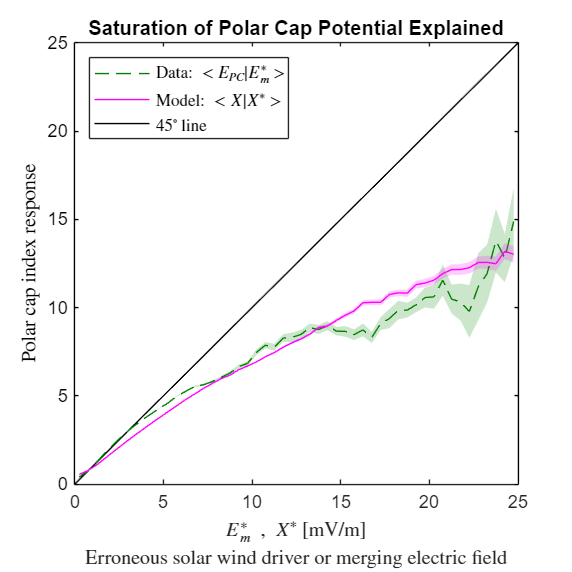

if setExportFig
export_fig([outputFolder,'Figure1B.png'], ...
    '-r600','-png','-nocrop',figM2);
export_fig([outputFolder,'Figure1B.pdf'], ...
    '-r600','-pdf','-nocrop',figM2);
end

## Validating the model

### Normalized marginal error distribution matches well

By comparing how well the variability between PCI and $E_m$ is captured, by $X$ and $X^*$, we can validate the stochastic model. 

$\textrm{error}=X^* -X$ ; Normalized $\textrm{error}=\frac{X^* -X}{X}$

Overall, the plot of the marginal error distribution below suggests that the model is accurately modeling the uncertainties. However, there is scope for improvement of the error model, since the model might be slightly over-estimating the probability of small uncertainties and underestimating the probability of large uncertainties, as compared to the data. 

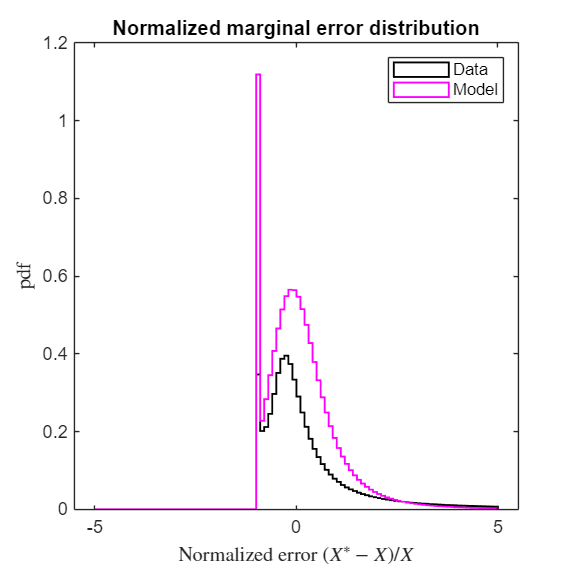

f5=figure; 
resize_figure(f5,2*55,2*55);
xBin3 = -5:0.1:5;
histogram((Xm2(:)-PCC(:))./PCC(:),xBin3,'Normalization','pdf', ...
    'DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
hold on;
histogram((WI(:)-XI(:))./XI(:),xBin3,'Normalization','pdf', ...
    'DisplayStyle','stairs','LineWidth',1,'EdgeColor','m');
xlabel('Normalized error $({X}^* - {X})/{X}$');
ylabel('pdf');
legend('Data','Model');
title('Normalized marginal error distribution','Interpreter',"none");

### Normalized conditional error distributions of data and model match (Figure ED6)

[PegX,XPegX,YPegX] = conditional_pdf((WI(:)-XI(:))./XI(:),XI(:),-2:0.1:2,0:1:20);
[Pe2gX,XPe2gX,YPe2gX] = conditional_pdf((Xm2(:)-PCC(:))./PCC(:),PCC(:),-2:0.1:2,0:1:20);

Below we plot a more complete picture of the uncertainties: the conditional probability density of the normalized error, $\frac{\left(X^* -X\right)}{X}$, for both data and model, varying with $X\ldotp$ If the variance (or spread) of this normalized conditional error distribution was constant with $X$, instead of decreasing linearly with $X$, it would mean that the "error" or variability is heteroscedastic as opposed to homoscedastic. Homoscedasticity is the general assumption when it comes to error distributions. As you see from the plot below, this is not a good assumption here, and we need the model to capture the heteroscedacity. 

In our case, the spread of the normalized error distribution increases with $X$, defined approximately by the bayanefit function displayed in a previous figure.

**Figure ED7: Conditional normalized error distribution** 

The conditional probability density of the normalized error (Left) is broadly captured by the model (Right).

figS7=figure;
resize_figure(figS7,2*55,2*120);

t=tiledlayout(1,2,'TileSpacing','loose');
title(t,'Comparing the Normalized Error Distribution between data and model');

nexttile
plot_2D_error(XPe2gX, YPe2gX, Pe2gX,'$P({E}^*_m-E_{PC}/E_{PC}|E_{PC})$');

caxis([0,1]);
ylabel('$E_{PC}$ [mV/m]','Interpreter','latex');
xlabel('$({E}^*_{m}-E_{PC})/E_{PC}$','Interpreter','latex');
xlim([-2,2]);
title('Data');

nexttile
plot_2D_error(XPegX, YPegX, PegX,'$P({X}^*-{X}/{X}|{X})$');

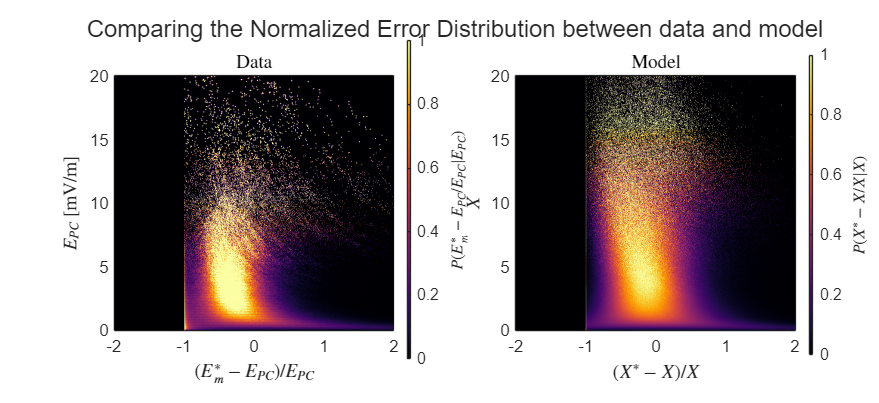

caxis([0,1]);
xlim([-2,2]);
colormap(inferno);
title('Model');
ylabel('$X$','Interpreter','latex');
xlabel('$ ({X}^* -{X} )/{X}$','Interpreter','latex');
if setExportFig
export_fig([outputFolder,'FigureED6.png'], ...
    '-r600','-png','-nocrop',figS7);
end

### Probability distributions match (Figure ED1, ED5)

In the following figure, in panel 1, we compare $\textrm{pdf}\left(\textrm{PCI}\right)$ and $\textrm{pdf}\left(X\right)$. As $\textrm{pdf}\left(X\right)$ is an input to the model and inspired from $\textrm{pdf}\left(\textrm{PCI}\right)$, as we assume $X\proptoY_{\textrm{PC}} ,\textrm{where}\;Y_{\textrm{PC}} =\textrm{PCI}$. There is no surprise that they are similar. 

However, in the second panel $\textrm{pdf}\left(E_m \right)$ from data is shown with $\textrm{pdf}\left(X^* \right)$ which is calculated by the model. The fact that **they are very similar**, should give us more confidence in the validity of our assumed stochastic model between $X^*$ and $X$. 

**Extended Data Figure 1: Input to the model has a similar pdf as the of **$E_{PC}$, proxy for the true shocked solar wind driver ${E}^{sh}_m$. 

figS1=figure; 
XBinsLog = logspace(-1,log10(25),100);
resize_figure(figS1,2*55,2*55);

nexttile
histogram(PCC,XBinsLog,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
hold on;
histogram(XI,XBinsLog,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','m');
hold on;

set(gca,'XScale','log','YScale','log');
ylim([10^-10,100]);
xlim([10^-1,25]);
legend('Data: $pdf(E_{PC})$','Model input: $pdf( {X} )$','Interpreter','latex')
xlabel('$E_{PC} \ , \ {X}$ [mV/m]');
ylabel('$pdf$');
title('Comparing model input to data');

**Figure ED4: Output of the model matches with data as well.** 

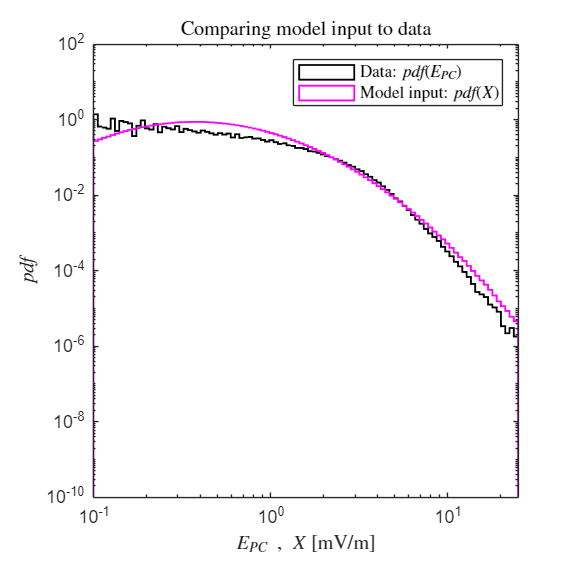


figS5=figure; 
resize_figure(figS5,2*55,2*55);
histogram(Xm,XBinsLog,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
hold on;
histogram(WI,XBinsLog,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','m');
set(gca,'XScale','log','YScale','log');
ylim([10^-10,100]);
xlim([10^-1,25]);
legend('Data: $ pdf({E}^*_m) $ ','Model: $ pdf({X}^*) $','Interpreter','latex');
xlabel('$ {E}^*_m \ , \ {X}^{*} $ [mV/m]');
ylabel('$pdf$');
if setExportFig
title('Comparing model output to data');
export_fig([outputFolder,'FigureED1.png'], ...
    '-r600','-png','-nocrop',figS1);
export_fig([outputFolder,'FigureED1.pdf'], ...
    '-r600','-pdf','-nocrop',figS1);
end

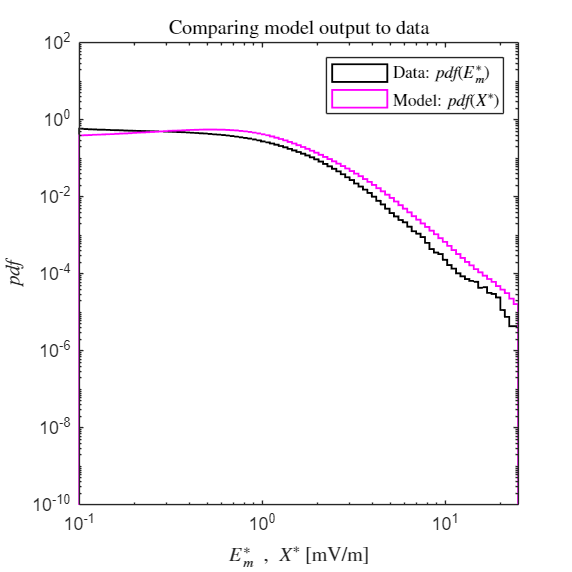

if setExportFig
export_fig([outputFolder,'FigureED4.png'], ...
    '-r600','-png','-nocrop',figS5);
export_fig([outputFolder,'FigureED4.pdf'], ...
    '-r600','-pdf','-nocrop',figS5);
end

### Slope of conditional expectations match

The slope $$\frac{d<X|X^*>}{dX}$$  of the conditional expectations shown in the main result, demonstrates the nature of the non-linear relationship between $\textrm{PCI}$ and ${E^* }_m$. And it turns out the model predicts the behavior of this slope, varying with $X$, almost exactly as observed in the data, up to 15 mV/m, after which the data is too sparse to take the slopes seriously. 

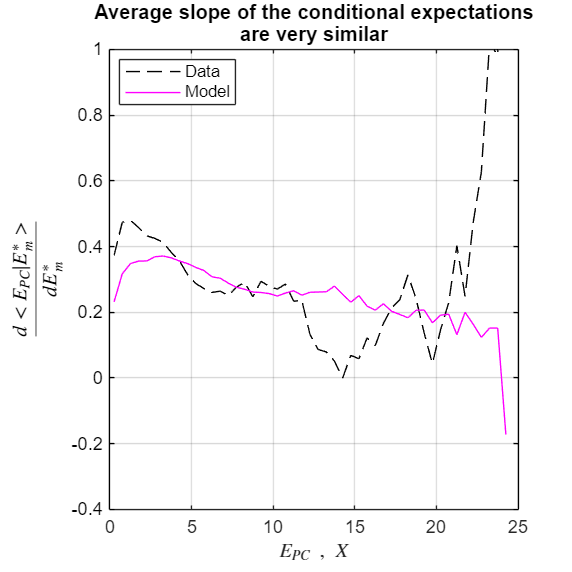

fig3=figure;
resize_figure(fig3,2*55,2*55);

plot(EPCCgW.XBins(1:end-1),smooth(diff(EPCCgW.YgX),10),'--k');

set(gca,'YColor','k');
ylabel('$\frac{d<E_{PC}|{E}^*_m>}{d{E}^*_m}$');
ylim([-0.4,1]);
xlim([0,25]);
grid on
hold on;
plot(EXIgWI.XBins(1:end-1),smooth(diff(EXIgWI.YgX),10),'m');
ylim([-0.4,1]);
xlabel('$E_{PC}\ , \ X$');
xlim([0,25]);
legend('Data','Model','Location','best');
title({'Average slope of the conditional expectations','are very similar'},'Interpreter',"none");

### Autocorrelation functions match

Finally, we compare the autocorrelation of the time series between the data and its corresponding counterparts in the model. Panel 1, compares ACF of $\textrm{PCI}$ and $X$. But since the ACF of $X$ is an input to the model inspired from $\textrm{PCI}$, there is no surprise in their similarity. However, in panel 2, the similarity between the ACF of ${E^* }_m$ and $X^*$, which is an output of the model, is quite striking. And it again ought to increase our confidence in the validity of the stochastic model.  

M = interp_nans(WI')';
[RArrayXN,lagXN] = find_correlation(M-nanmean(M,1),nSubsetSample,nEnsemblesM,1);

acf_XN = mean(RArrayXN(:,1:2^12)./RArrayXN(:,1));
lag_XN = lagXN(1:2^12);
acf_fit_XN = fit(lag_XN,acf_XN','spline'); % Fitting the ACF with a spline!

M = interp_nans(XI')';
[RArrayXI,lagXI] = find_correlation(M-nanmean(M,1),nSubsetSample,nEnsemblesM,1);

acf_XI = mean(RArrayXI(:,1:2^12)./RArrayXI(:,1));
lag_XI = lagXI(1:2^12);
acf_fit_XI = fit(lag_XI,acf_XI','spline'); % Fitting the ACF with a spline!

figS2=figure; 
resize_figure(figS2,2*55,2*55);

plot(tInd./60,acf_fit_PCC(tInd),'--k');
hold on;
plot(tInd./60,acf_fit_XI(tInd),'-m');
ylim([0,1]);
xlim([-1,14]);
legend('Data: $<E_{PC}(t) E_{PC}(t + \tau)>$','Model: $<{X}(t) {X}(t+\tau)>$','Interpreter','latex');
title('Comparing ACFs of model input and data');
xlim([-1, 14]);
ylabel('Autocorrelation Functions');

xlabel('$\tau$ [Hours]');

### **ACF of model input is made to be similar to the data (Figure ED2)**

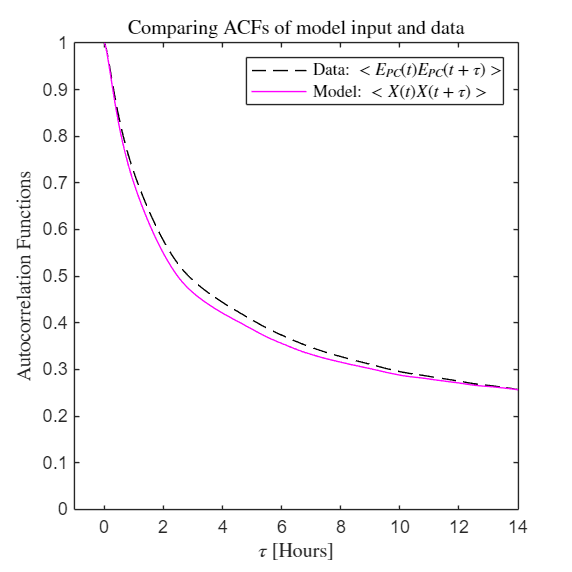

if setExportFig
export_fig([outputFolder,'FigureED2.png'], ...
    '-r600','-png','-nocrop',figS2);
export_fig([outputFolder,'FigureED2.pdf'], ...
    '-r600','-pdf','-nocrop',figS2);
end

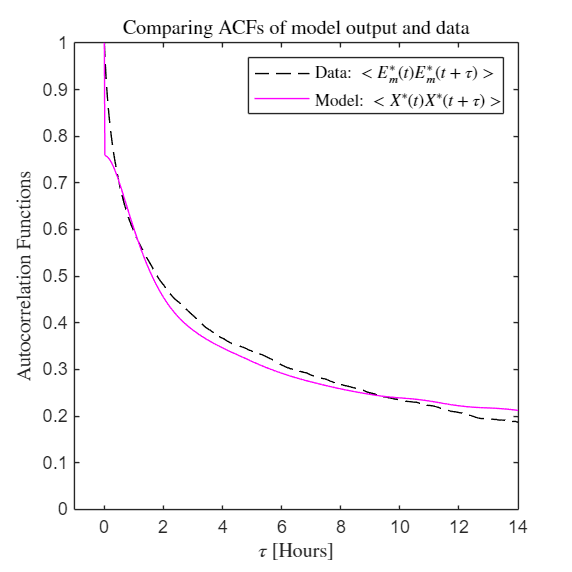

fig31=figure;
resize_figure(fig31,2*55,2*55);
tInd = 0:1000;
plot(tInd./60,acf_fit_Xm(tInd),'--k');
hold on;
plot(tInd./60,acf_fit_XN(tInd),'-m');
ylim([0,1]);
xlim([-1,14]);
xlabel('$\tau$ [Hours]');
ylabel('Autocorrelation Functions');
legend('Data: $<{E}^*_m(t){E}^*_m(t + \tau)>$','Model: $<{X}^*(t) {X}^*(t+ \tau)>$','Interpreter','latex');
title('Comparing ACFs of model output and data');

### Variation of variability (or error) match

Looking at some summary statistics of the normalized conditional error distribution, we can get a better picture of the model vailidity with respect to how well it captures the variation of variability/error with $X$. In the figure below, that provides three stunning similarities between model and data.

Panel 1b: Spread of the normalized error distribution varies with $X$ in the same manner for data and model. The model underestimates the spread in error for $X$ values < 10 mV/m. The model overestimates it for X>10 mV/m, this could be because the variance of PCI for values of ${E^* }_m >10\;$mV/m is likely underestimated because of the sparse data. 

Panel 2a and Panel 2b: Show the bias in the variability or error, and how it increases with $X\ldotp$ The model captures this bias perfectly well, except for the normalized bias below 10 mV/m which is overestimated, probably because of overestimating the probability of low error values shown previously. And this bias is a result of the uncertainty in the propagation delay (${\textrm{dt}}_1 +{\textrm{dt}}_2$), and the heteroscedastic variability $\left(\epsilon \;\right)$. 

EeXIgWI = create_curve(WI(:),WI(:)-XI(:),XBins);
EeXIgWIs = create_curve(Xm2(:),Xm2(:)-PCC(:),XBins);

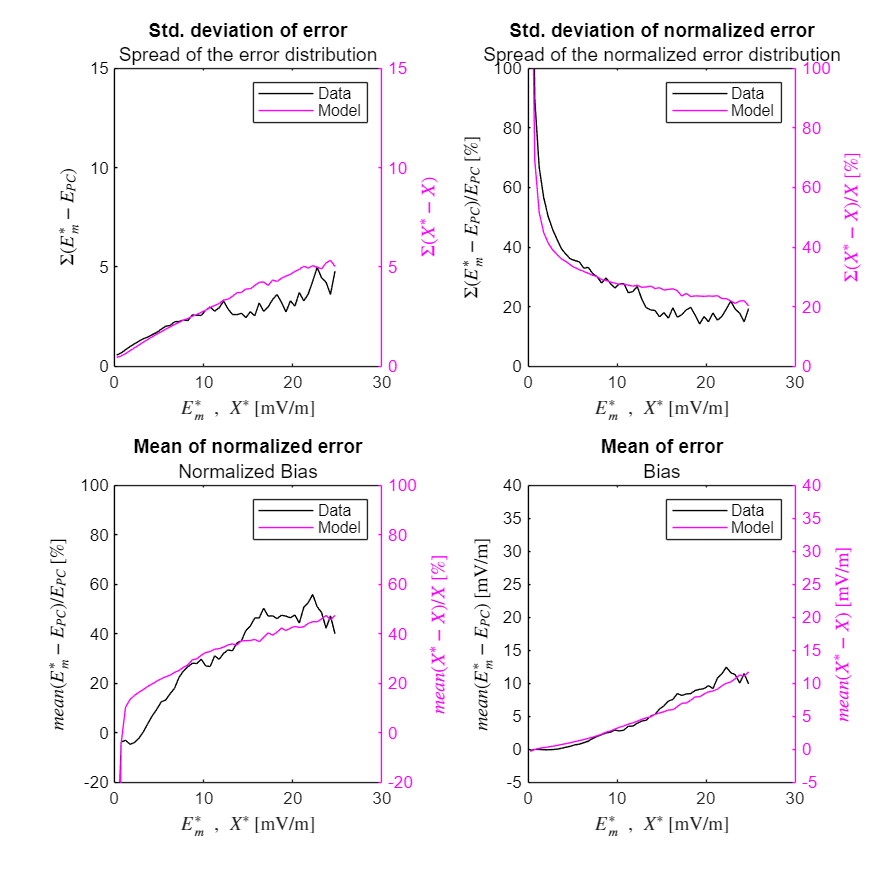

fig4=figure; 
resize_figure(fig4,2*120,2*120);

t=tiledlayout(2,2,"TileSpacing","compact");

nexttile

yyaxis left
plot(EeXIgWIs.XBins,EeXIgWIs.stdYgX,'k');
ylim([0,15]);
ylabel('$\Sigma({E}^*_m-E_{PC})$');
set(gca,'YColor','k');

yyaxis right
plot(EeXIgWI.XBins,EeXIgWI.stdYgX,'m');
ylim([0,15]);
set(gca,'YColor','m');
ylabel('$ \Sigma({X}^*-{X}) $');
title('Std. deviation of error','Spread of the error distribution','Interpreter',"none");
legend('Data','Model');
xlabel('${E}^*_m \ , \ {X}^*$ [mV/m]');

nexttile

yyaxis left
plot(EeXIgWIs.XBins,100.*EeXIgWIs.stdYgX./EeXIgWIs.XBins,'k');
ylim([0,100]);
ylabel('$\Sigma({E}^*_m-E_{PC}) / E_{PC}$  [\%]');
set(gca,'YColor','k');

yyaxis right
plot(EeXIgWI.XBins,100.*EeXIgWI.stdYgX./EeXIgWI.XBins,'m');
ylim([0,100]);
set(gca,'YColor','m');
ylabel('$\Sigma({X}^*-{X}) / {X} $ [\%]');
title('Std. deviation of normalized error','Spread of the normalized error distribution','Interpreter',"none");
legend('Data','Model');
xlabel('${E}^*_m \ , \ {X}^*$ [mV/m]');

nexttile

yyaxis left
plot(EeXIgWIs.XBins,100.*EeXIgWIs.YgX./EeXIgWIs.XBins,'k');
ylim([-20,100]);
ylabel('$mean({E}^*_m-E_{PC}) / E_{PC}$  [\%]');
set(gca,'YColor','k');

yyaxis right
plot(EeXIgWI.XBins,100.*EeXIgWI.YgX./EeXIgWI.XBins,'m');
ylim([-20,100]);
set(gca,'YColor','m');
ylabel('$mean({X}^*-{X}) / {X} $ [\%]');
title('Mean of normalized error','Normalized Bias','Interpreter',"none");
legend('Data','Model');
xlabel('${E}^*_m \ , \ {X}^*$ [mV/m]');

nexttile

yyaxis left
plot(EeXIgWIs.XBins,EeXIgWIs.YgX,'k');
ylim([-5,40]);
ylabel('$mean({E}^*_m-E_{PC})$  [mV/m]');
set(gca,'YColor','k');

yyaxis right
plot(EeXIgWI.XBins,EeXIgWI.YgX,'m');
ylim([-5,40]);
set(gca,'YColor','m');
ylabel('$mean({X}^*-{X})$ [mV/m]');
title('Mean of error','Bias','Interpreter',"none");
legend('Data','Model');
xlabel('${E}^*_m \ , \ {X}^*$ [mV/m]');

### Predicting nature of random error between estimate and true value (Figure ED5)

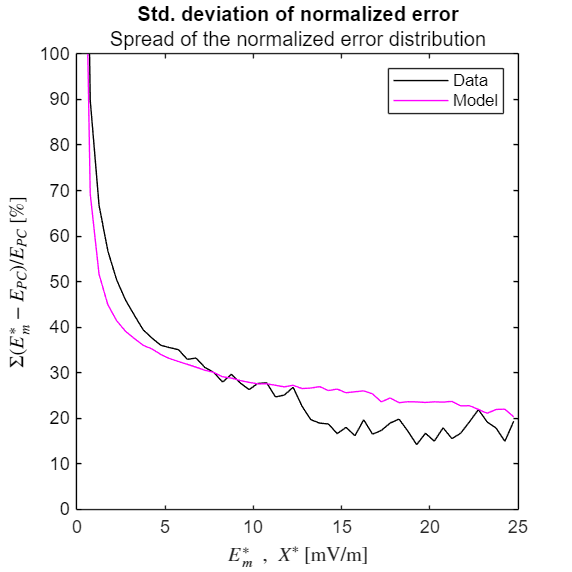

figS6=figure; 
resize_figure(figS6,2*55,2*55);
plot(EeXIgWIs.XBins,100.*EeXIgWIs.stdYgX./EeXIgWIs.XBins,'k');
ylim([0,100]);
ylabel('$\Sigma({E}^*_m-E_{PC}) / E_{PC}$  [\%]');
set(gca,'YColor','k');
hold on;
plot(EeXIgWI.XBins,100.*EeXIgWI.stdYgX./EeXIgWI.XBins,'m');
ylim([0,100]);

title('Std. deviation of normalized error','Spread of the normalized error distribution','Interpreter',"none");
legend('Data','Model');
xlabel('${E}^*_m \ , \ {X}^*$ [mV/m]');
if setExportFig
export_fig([outputFolder,'FigureED5.png'], ...
    '-r600','-png','-nocrop',figS6);
export_fig([outputFolder,'FigureED5.pdf'], ...
    '-r600','-pdf','-nocrop',figS6);
end

### Non-linear conditional bias (Figure ED7)

The model reproduces the non-linear conditional bias observed in the data extraordinarily well, by merely assuming random uncertainty in the estimate of the solar wind electric field at the polar cap. 

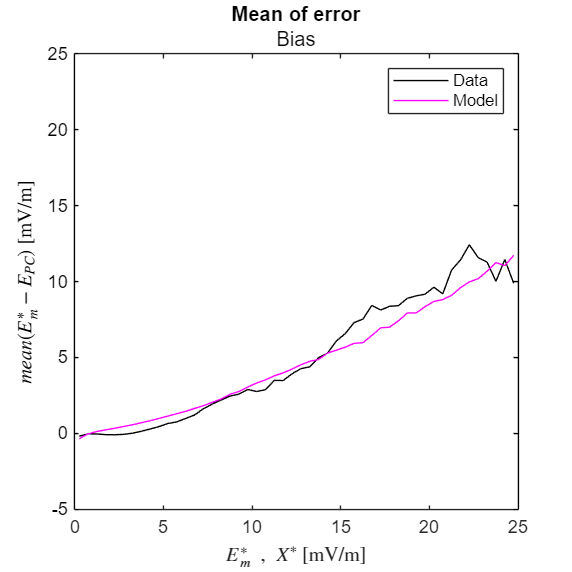

figS8=figure; 
resize_figure(figS8,2*55,2*55);
plot(EeXIgWIs.XBins,EeXIgWIs.YgX,'k');
ylim([-5,40]);
ylabel('$mean({E}^*_m-E_{PC})$  [mV/m]');
set(gca,'YColor','k');
hold on;
plot(EeXIgWI.XBins,EeXIgWI.YgX,'m');
ylim([-5,25]);

title('Mean of error','Bias','Interpreter',"none");
legend('Data','Model');
xlabel('${E}^*_m \ , \ {X}^*$ [mV/m]');
if setExportFig
export_fig([outputFolder,'FigureED7.png'], ...
    '-r600','-png','-nocrop',figS8);
export_fig([outputFolder,'FigureED7.pdf'], ...
    '-r600','-pdf','-nocrop',figS8);
end

### Explaining the origin of the non-linear bias (Figure ED8)

The non-linear increase in bias that you see in the above plots, is a result of the tranformation of $X$ into $X^*$, despite the zero-mean random nature of propagation delay uncertainity, and the intrinsic scatter. 

Panel (Left): In the plot below, the left panel shows the probability distribution of $X$, colored in accordance with the value of $X$.

The stochstic model, transforms $X$ into $X^*$. 

Panel (Right): The right panel shows the probabiliy distribution of $X^*$, the transformed variable, but with the color still in accordance with the value of $X\;$- the input to the model. 

As you can see, a large proportional of small $X$ values, are now associated with large values of $X^*$. Naturally, this brings down the value of $X$ given a particular $X^*$ closer to the mean. This explains the bias. 

Why is the bias non-linear?

- The fact that there are far more values of $X$ at lower mangitudes, than higher magnitudes, due to the underlying probability distribution of $X$ being log-normal. 

- And the heteroscedastic nature of the scattering of $X$ (which implies a multiplicative error model, see [Carroll et al., 2006, Sec 4.5.2,](https://www.google.com/books/edition/Measurement_Error_in_Nonlinear_Models/9kBx5CPZCqkC?hl=en) that can cause a regression attenuation (bias) that is non-linear)

The above two facts are the reasons behind the non-linearity in the observed bias in the conditional expectation $<X|X^* >$ and also $<E_{\textrm{PC}} |{{\hat{\;E} }^* }_m >$.

nBins = length(XBinsLog);
[edges1, value1] = create_segmented_pdfs(XI,XI,XBinsLog,XBinsLog);
cf = inferno(nBins);

[edges2, value2] = create_segmented_pdfs(XI,WI,XBinsLog,XBinsLog);

figS9 = figure; 
resize_figure(figS9,2*55,2*120);
t=tiledlayout(1,2,"TileSpacing","tight");
title(t,'Explaining the statistical origin of the non-linear bias','Interpreter','none','FontSize',16);

nexttile
bar(log10(edges1),value1','BarLayout','stacked','BarWidth',1,'EdgeColor','none');
set(gca,'XScale','linear','YScale','log',...
    'XTick',log10([0.1,1,4,10,50]),'XTickLabel',{'0.1','1','4','10','50'});
colororder(cf);
xlabel('${X}$ [mV/m]');
ylabel('$pdf({X})$ [Count Density]');
title('Model input');
xlim([-1,2]);
ylim([10^-2,10^8]);

set(gca,'FontSize',14);

nexttile

bar(log10(edges2),value2','BarLayout','stacked','BarWidth',1,'EdgeColor','none');
set(gca,'XScale','linear','YScale','log',...
    'XTick',log10([0.1,1,4,10,50]),'XTickLabel',{'0.1','1','4','10','50'}, ...
    'YTickLabel',[]);
colororder(cf);
colormap(cf);



ylim([10^-2,10^8]);
xlim([-1,2]);
xlabel('${X}^*$ [mV/m]');
title({'Model output: proportion of','corresponding inputs in color'});
set(gca,'FontSize',14);
cb=colorbar_thin('YLabel','${X}$');

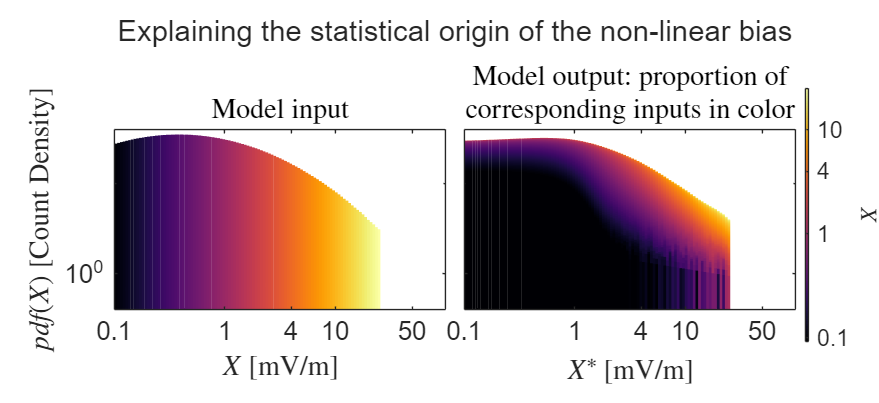

caxis(log10([edges1(1)-0.01,edges1(end)]));
cb.Ticks=log10([0.1, 1, 4, 10, 50]);
cb.TickLabels=([0.1, 1, 4, 10, 50]);
if setExportFig
export_fig([outputFolder,'FigureED8.png'], ...
    '-r600','-png','-nocrop',figS9);
export_fig([outputFolder,'FigureED8.pdf'], ...
    '-r600','-pdf','-nocrop',figS9);
end

### Non-linear bias in the Conditional PDFs (Figure 3AB)

The conditional probability distributions, also show the non-linear bias clearly, in the data and the model. The left panel of the figure below, shows the conditional probability distribution of $\textrm{PCI}|{E^* }_m$ derived from data, and the conditional pdf of $X|X^*$ from the model. The similarities are visible between the distributions. 

[PXgW,XPXgW,YPXgW] = conditional_pdf(XI(:),WI(:),0:1:40,0:1:40);
[PXgWs,XPXgWs,YPXgWs] = conditional_pdf(PCC(:),Xm(:),0:1:40,0:1:40);


fig3ab=figure; 
resize_figure(fig3ab,2*55,2*120);
t=tiledlayout(1,2);
title(t,'Non-linear bias in the Conditional Probability Densities','Interpreter','none');

nexttile 
colormap(inferno);
plot_2D_error(XPXgWs, YPXgWs, PXgWs','$pdf(E_{PC}|\hat{E}^*_m)$');

caxis([0,0.5]);
ylabel('$E_{PC}$','Interpreter','latex');
xlabel('$\hat{E}^*_m$');
hold on;
p3 = plot(XBins,XBins,'c');
hold on;
p4 = plot_curve(EPCCgW,'g');
xlim([0,25]);
ylim([0,25]);
legend([p3,p4],{'$<E_{PC}|{E}_m>$','$<E_{PC}|{E}^*_m>$'},'Location','northwest','Interpreter','latex');
title('Data: $pdf(E_{PC}|{E}_m)$');

nexttile
colormap(inferno);
plot_2D_error(XPXgW, YPXgW, PXgW','$pdf({X}|{X}^*)$');

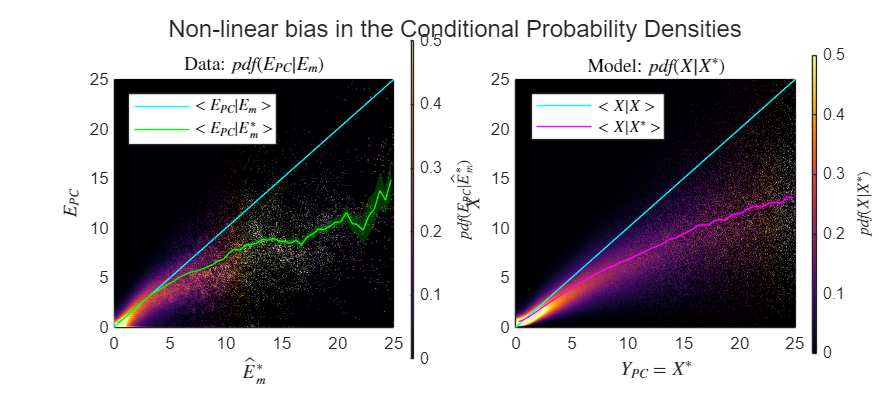

caxis([0,0.5]);
ylabel('${X}$','Interpreter','latex');
xlabel('$Y_{PC}={X}^*$');
hold on;
p3 = plot(XBins,XBins,'c');
hold on;
p4 = plot_curve(EXIgWI,'m');
xlim([0,25]);
ylim([0,25]);
legend([p3,p4],{'$<{X}|{X}>$','$<{X}|{X}^*>$'},'Location','northwest','Interpreter','latex');
title('Model: $pdf({X}|{X}^*)$');
if setExportFig
export_fig([outputFolder,'Figure3AB.png'], ...
    '-r600','-png','-nocrop',fig3ab);
end

### Normalized conditional error distribution, conditioned on X*

The error distirbution plots differ based on the variable it is conditioning on. Here you can see the non-linear bias, shown here. 

[PegW,XPegW,YPegW] = conditional_pdf((WI(:)-XI(:))./XI(:),WI(:),-2:0.1:2,0:1:20);
[Pe2gW,XPe2gW,YPe2gW] = conditional_pdf((Xm2(:)-PCC(:))./PCC(:),Xm2(:),-2:0.1:2,0:1:20);

figA1=figure;
resize_figure(figA1,2*55,2*120);

t=tiledlayout(1,2);
title(t,'Comparing the Normalized Error Distribution between data and model');
nexttile
plot_2D_error(XPe2gW, YPe2gW, Pe2gW,'$P({E}^*_m-E_{PC}/E_{PC}|{E}^*_m)$');

caxis([0,1]);
ylabel('${E}^*_{m}$ [mV/m]','Interpreter','latex');
xlabel('$({E}^*_{m}-E_{PC})/E_{PC}$','Interpreter','latex');
xlim([-2,2]);
title('Data');

nexttile
plot_2D_error(XPegW, YPegW, PegW,'$P({X}^*-{X}/{X}|{X}^*)$');

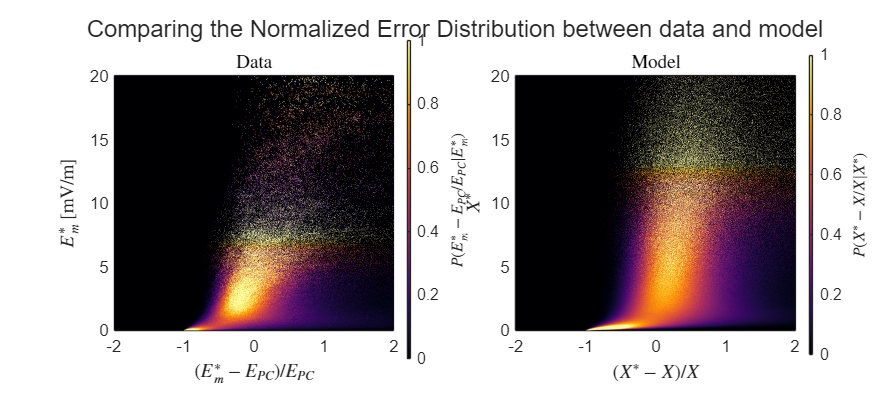

caxis([0,1]);
xlim([-2,2]);
colormap(inferno);
title('Model');
ylabel('${X}^*$','Interpreter','latex');
xlabel('$ ({X}^* -{X} )/{X}$','Interpreter','latex');

## Result 2: Saturation of Auroral Currents Explained (as well)

For the sake of argument, if we assume, the auroral currents increase linearly with electric field in the ionosphere, such as $Y_{\textrm{SML}} =-120\;X+N\left(0,\sigma \;\right)$, then the conditional expectation $<Y|X^* >$will non-linearly increase with $X^*$. And this non-linearity, is exactly similar to what we observe from data. 

In the plot below, the green-line, is the conditional expectation of the auroral electrojet strength given time-shifter solar wind geoeffective field: $<\textrm{SML}|{E^* }_m >$. This matches exactly with the model prediction $<Y|X^* >$, the magneta line, provided we make the above assumption of a linear relationship between $Y_{\textrm{SML}}$ (model proxy for $\textrm{SML}$) and $Y_{\textrm{PC}} =X$ (model proxy for $E_{\textrm{PC}}$, effective ionospheric electric field). 

This result implies, that the non-linear relationship between auroral electrojet current and geoeffective field, can be explained by our uncertainties in propagating geoeffective field from L1 measurements to the ionosphere - all the while the ionospheric current is a linear function of the effective ionospheric electric field or polar cap electric field. 

YS = Fsml(datenum(XmTime));
EYsgWs = create_curve(Xm2(:),YS(:),XBins);
EYsgPCC = create_curve(PCC(:),YS(:),XBins);
if ~setLoadExistingData
    Y = -120.*XI + random('Normal',0,5,nSubsetSample,nEnsemblesM)';
end

EYgW = create_curve(WI(:),Y(:),XBins);
EYgX = create_curve(XI(:),Y(:),XBins);

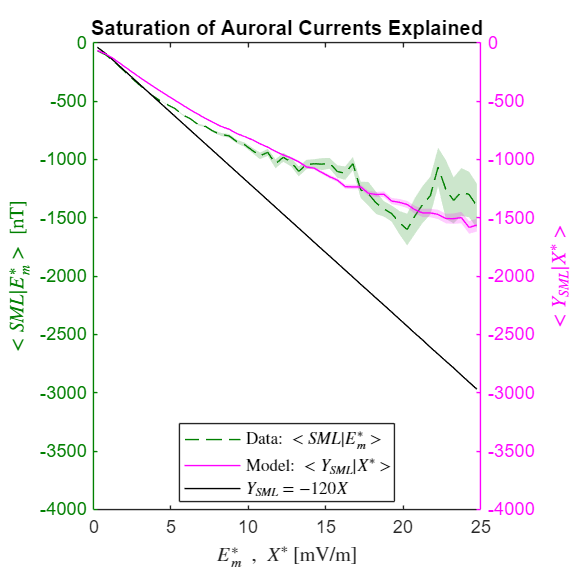

fig7 =figure;
resize_figure(fig7,2*55,2*55);
yyaxis right
p1 = plot_curve(EYgX,'k');
hold on;
p2 = plot_curve(EYgW,'m');
set(gca,'YColor','m');
p2.LineStyle='-';
ylabel('$<Y_{SML}|{X}^*>$');
ylim([-4000,0]);

yyaxis left
p3 = plot_curve(EYsgWs,[0 0.5 0]);
p3.LineStyle='--';

set(gca,'YColor',[0 0.5 0]);
ylim([-4000,0]);
xlabel('${E}^*_m \ , \ {X}^*$ [mV/m]','Interpreter','latex');
ylabel('$<SML|{E}^*_m>$ [nT]','Interpreter','latex');
legend([p3,p2,p1],{'Data: $<SML|{E}^*_m>$ ','Model: $<Y_{SML}|{X}^*>$ ','$Y_{SML}=-120 X$'},'Location','best','Interpreter','latex');
title('Saturation of Auroral Currents Explained','Interpreter',"none");

## Correcting for the bias: Regression calibration

When we have the conditional expectation of the true value given an erroneous estiamte such as $f_r \left(x\right)=\langle X|X^* =x\rangle$, such as what we obtained in result 1 and result 2, these can be considered the best estimate of the true values given the erroroneous estimate. $f_r \left(x\right)$can be used to statistically correct ${E^* }_m$ to its most likely estimate of the true value $E_m^c$. Hence, the input solar wind forcing variable (X-axis in result 1 and 2) can be resplaced with the statistically corrected variable ${E^c }_m$. This is simply ${E^c }_m =\langle X|X^* ={E^* }_m \rangle \;$. We carry this out by interpolating the best estimates of the model true values given model erroneous values $\langle X|X^* =x\rangle$ when $x={E^* }_m \;$.   

% Calibrating Em
Xm2C=interp1(EXIgWI.XBins,EXIgWI.YgX,Xm2(:),'linear','extrap'); % Regression calibration; Stretching the X-axis according to the regression function <X|X*>
[PXgWCs,XPXgWCs,YPXgWCs] = conditional_pdf(PCC(:),Xm2C(:),0:1:40,0:1:40);
EPCCgWC = create_curve(Xm2C,PCC,XBins);

figA5=figure; 
resize_figure(figA5,2*55,2*120);
t=tiledlayout(1,2);

nexttile 
colormap(inferno);
PXgWs(isinf(PXgWs)|PXgWs>100)=0;
plot_2D_error(XPXgWs, YPXgWs, PXgWs','$pdf(E_{PC}|{E}^*_m)$');

caxis([0,0.5]);
ylabel('$E_{PC}$','Interpreter','latex');
xlabel('${E}^*_m$','Interpreter','latex');
hold on;
p3 = plot(XBins,XBins,'c');
hold on;
p4 = plot_curve(EPCCgW,'g');
xlim([0,25]);
ylim([0,25]);
legend([p3,p4],{'$<E_{PC}|{E}_m>$','$<E_{PC}|{E}^*_m>$'},'Location','northwest','Interpreter','latex');
title('Data: $pdf(E_{PC}|{E}^*_m)$');

nexttile 
colormap(inferno);
PXgWCs(isinf(PXgWCs)|PXgWCs>100)=0;
plot_2D_error(XPXgWCs, YPXgWCs, PXgWCs','$pdf(E_{PC}|{E}^c_m)$');

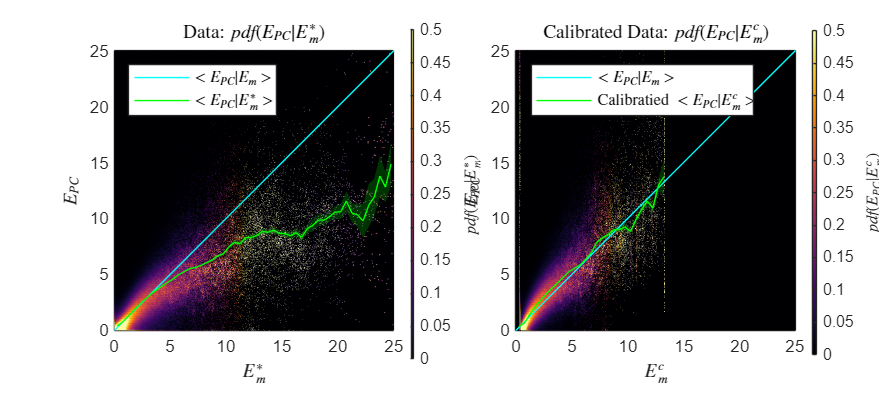

caxis([0,0.5]);
ylabel('$E_{PC}$','Interpreter','latex');
xlabel('${E}^c_m$','Interpreter','latex');
hold on;
p3 = plot(XBins,XBins,'c');
hold on;
p4 = plot_curve(EPCCgWC,'g');
xlim([0,25]);
ylim([0,25]);
legend([p3,p4],{'$<E_{PC}|{E}_m>$','Calibratied $<E_{PC}|{E}^c_m>$'},'Location','northwest','Interpreter','latex');
title('Calibrated Data: $pdf(E_{PC}|{E}^c_m)$');

### Corrected polar cap potential response and auroral electrojet response (Figure 4)

The corrected values, now demonstrate a linear correlation between solar wind forcing, and polar cap potential and auroral electrojet response! 

EYsgEmC = create_curve(Xm2C(:),YS(:),XBins);

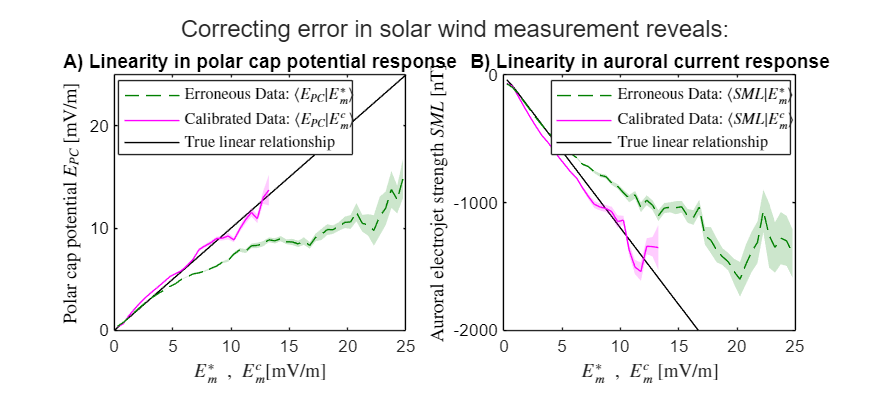

figM3 =figure; 
resize_figure(figM3,2*55,2*120);
t=tiledlayout(1,2,"TileSpacing","compact");
title(t,'Correcting error in solar wind measurement reveals:','Interpreter','none')
nexttile 
p1 = plot(XBins,XBins,'k');
hold on;
p2 = plot_curve(EPCCgWC,'m');
set(gca,'YColor','m');
p2.LineStyle='-';
ylabel('$<Y|{X}^*>$');
ylim([0,25]);

p3 = plot_curve(EPCCgW,[0 0.5 0]);
p3.LineStyle='--';
set(gca,'YColor',[0 0 0],'YTick',[0,10,20]);

xlabel('${E}^*_m \ , \ {E}^c_m $[mV/m]','Interpreter','latex');
ylabel('Polar cap potential $E_{PC}$ [mV/m]','Interpreter','latex');
legend([p3,p2,p1],{'Erroneous Data: $\langle E_{PC}|{E}^*_m \rangle $ ','Calibrated Data: $\langle  E_{PC}|{E}^c_m \rangle $ ','True linear relationship'},'Location','best','Interpreter','latex');
title('A) Linearity in polar cap potential response','Interpreter',"none");

nexttile 
p1 = plot_curve(EYgX,'k');
hold on;
p2 = plot_curve(EYsgEmC,'m');
set(gca,'YColor','m');
p2.LineStyle='-';
ylabel('$<Y|{X}^*>$');
ylim([-2000,0]);

p3 = plot_curve(EYsgWs,[0 0.5 0]);
p3.LineStyle='--';
set(gca,'YColor',[0 0 0],'YTick',[-2000,-1000,0]);

xlabel('$E^*_m \ , \ E^c_m$ [mV/m]','Interpreter','latex');
ylabel('Auroral electrojet strength $SML$ [nT]','Interpreter','latex');
legend([p3,p2,p1],{'Erroneous Data: $\langle SML|{E}^*_m \rangle $ ','Calibrated Data: $\langle SML|{E}^c_m \rangle$ ','True linear relationship'},'Location','best','Interpreter','latex');
title('B) Linearity in auroral current response','Interpreter',"none");
if setExportFig
export_fig([outputFolder,'Figure4.png'], ...
    '-r600','-png','-nocrop',figM3);
export_fig([outputFolder,'Figure4.pdf'], ...
    '-r600','-pdf','-nocrop',figM3);
end

% Saving the run
if ~setLoadExistingData
save_previous_run_filename=[DataDir,'polar_cap_previous_run.mat'];
% Save all variables that exist in the workspace
save(save_previous_run_filename, 'wind', 'pci', 'Fsml', 'Xm', 'XmTime', 'Fpcc', ...
        'acf_fit_Xm', 'acf_fit_PCC', 'acf_fit_var', 'X', 'terr1', ...
        'terr2', 'HNoise', 'HNoiseX', 'HNoise_B25', 'HNoiseX_B25', 'Y', ...
        '-v7.3'); % -v7.3 allows for larger files if needed
end

## Functions

function [y] = f(x,b,c)

**f(): **$f_{\sigma \;} \left(x,c,b\right)=c\;{\left(\frac{x}{40}\right)}^b$ - capturing the heteroscedastic nature of intrinsic scatter in the propagation of $E_m$ at L1 to the ionosphere. 

y = 0.1+c.*((x/40).^b);
y(x>12) = 0.1+c.*((12/40).^b);
end

function [wind, pci, Fsml, Em, time, Fpcc, acf_fit_E, acf_fit_PCC, acf_fit_var]= initialize(superMagFile,windDataFolder,polarCapDataFolder)

**Initialize()** : Extracts all relevant data. 

% Extract SML values
superMag = extract_superMag(superMagFile);
Fsml = griddedInterpolant(datenum(superMag.datetime),superMag.SML,'linear','none');

% Extract WIND measurements, especially Em values
wind = extract_set_of_data(windDataFolder,'wind'); 

% Extract polar cap index
pci = extract_set_of_data_PCI(polarCapDataFolder);
pci.PCN(pci.PCN>=999)=nan;
pci.PCS(pci.PCS>=999)=nan;
temp.PCN=pci.PCN;
temp.PCS=pci.PCS;
temp.PCN(temp.PCN<=0)=0;
temp.PCS(temp.PCS<=0)=0;
pci.PCC = 0.5.*(temp.PCN + temp.PCS); % Calculating PCC from PCN and PCS
Fpcc = griddedInterpolant(datenum(pci.datetime),pci.PCC,'linear','none');


%Extracting dataset when both PCI and Wind measurements are available
[~,piI,wiI]=intersect(pci.datetime,wind.datetime); % Simultaneous time from WIND, GEOTAIL and PCI
wind2 = wind(wiI,:);
 
Em = wind2.E_kl.*10^-3; % How is EKL calculated is important
time = wind2.datetime; % Common time
PCC = Fpcc(datenum(time));

error = Em-PCC;

% Finding ACF of X, from data; %Explain how ACF is calculated in reference

% Calculating ACF of Xm
[Me, nSample,  nEnsemble]  = split_series(wind.E_kl.*10^-3,2^13);
[RArraye,lage] = find_correlation(Me-nanmean(Me,1),nSample,nEnsemble,1);

acf_E = mean(RArraye(:,1:2^12)./RArraye(:,1));
lag_E = lage(1:2^12);
acf_fit_E = fit(lag_E,acf_E','spline'); % Fitting the ACF with a spline!

% Calculating ACF of PCC
[Me1, nSample1,  nEnsemble1]  = split_series(pci.PCC,2^13);
[RArraye1,lage1] = find_correlation(Me1-nanmean(Me1,1),nSample1,nEnsemble1,1);

acf_PCC = mean(RArraye1(:,1:2^12)./RArraye1(:,1));
lag_PCC = lage1(1:2^12);
acf_fit_PCC = fit(lag_PCC,acf_PCC','spline'); % Fitting the ACF with a spline!

% Calculating ACF of Error
[Me2, nSample2,  nEnsemble2]  = split_series(error,2^13);
[RArraye2,lage2] = find_correlation(Me2-nanmean(Me2,1),nSample2,nEnsemble2,1);

acf_var = mean(RArraye2(:,1:2^12)./RArraye2(:,1));
lag_var = lage2(1:2^12);
acf_fit_var = fit(lag_var,acf_var','spline'); % Fitting the ACF with a spline!

end

function [edges, value] = create_segmented_pdfs(X,Y,XBins,XSegments,normalizationStr)

**create_segmented_pdfs(): **Creating histograms of probability distributions, which can be colored to show a form of conditional probability distribution. (See figure).

if nargin<5
    normalizationStr = 'countdensity';
end

value = zeros(length(XSegments),length(XBins)-1);
for i=1:1:length(XSegments)
    if i==1
        [value(i,:),edges] = histcounts(Y(X<=XSegments(i)),XBins,'Normalization',normalizationStr);
        edges = edges(2:end) - (edges(2)-edges(1))/2;
    elseif i>1 && i < length(XSegments)
        value(i,:) = histcounts(Y(X>XSegments(i-1) & X<=XSegments(i)),XBins,'Normalization',normalizationStr);
    else
       value(i,:) = histcounts(Y(X>=XSegments(i-1)),XBins,'Normalization',normalizationStr);
    end
    
end

end


function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX, 'Color', color);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function p = plot_2D_error(Y,X,P,yLabel)
    p = pcolor(Y,X,P);
    set(p,'EdgeColor','none');
    colorbar_thin('YLabel',yLabel);
end

function curve = create_curve(X, Y, Ei)

if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E; 

end

function [fXgY,XX,YY] = conditional_pdf(X, Y, gridx, gridy)

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

sz = 2^10;
Y = Y(:);
Y(Y==999999)=nan;

[bandwidth,fXY,XX,YY]=kde2d([X,Y],sz,[min(gridx),min(gridy)],[max(gridx),max(gridy)]);
[fY, YY1] = ksdensity(Y,YY(:,1));

fXgY = fXY./repmat(fY,1,sz);


The above formula is basically equation 1, below. 

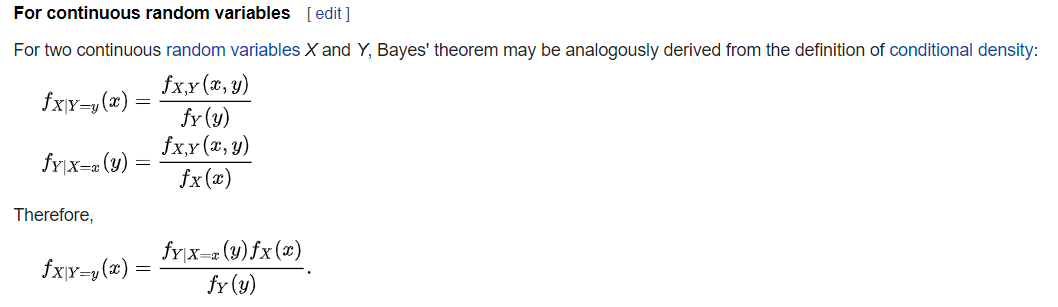


end


function [M, nSample, nEnsemble]= split_series(series,sampleSize,MaxNoOfMissingValues)
    if nargin<3
        MaxNoOfMissingValues=1000;
    end
        
    series = padarray(series,sampleSize-mod(length(series),sampleSize),'post');
    L = length(series); 
    M0 = reshape(series,sampleSize,[])';
    indx=sum(isnan(M0),2)>MaxNoOfMissingValues;
    l = 1:1:size(M0,1);
    k=1;
    for i=l(~indx)
        M(k,:) = M0(i,:);
        k=k+1;
    end
    nSample = size(M,2);
    nEnsemble = size(M,1);
    
    M = interp_nans(M')';
end

function [RArray,lag]=find_correlation(M,nSample,nEnsemble,sampleTime)
    dt = sampleTime;
    lag = fftshift(-nSample:1:nSample-1)'.*dt;
    xCell = mat2cell(M, ones(1,nEnsemble),nSample);
    [RArray] = cellfun(@(x) xcorr(x,'unbiased'),xCell,'UniformOutput',false);
    RArray = cell2mat(RArray);
    RArray(:,2:end+1) = RArray(:,1:end);
    RArray(:,1)=RArray(:,2);
    RArray = ifftshift(RArray);
end


function T1 = extract_data(loadFile)
        % Extract solar wind data from OMNI High Resolution space-craft specific files
        format = '%4f %4f %3f %3f %4f %4f %4.1f %6f %6.2f %6.2f %6.2f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %7f %6.2f %8.2f %8.2f %4f %8.1f %8.1f %8.1f %8.1f %7.2f %9.0f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %7f %7f';
        tempData = load_ascii_files(loadFile, format, 0);
        T.datetime = datetime(tempData{1},1,tempData{2},tempData{3},tempData{4},zeros(size(tempData{4})));
        T.timeshift = tempData{8}; T.timeshift(T.timeshift==999999) = nan;
        T.BxGSM = tempData{13};  T.BxGSM(T.BxGSM > 9999) = nan;
        T.ByGSM = tempData{16}; T.ByGSM(T.ByGSM > 9999) = nan;
        T.BzGSM = tempData{17}; T.BzGSM(T.BzGSM > 9999) = nan;
        T.velocity = tempData{23}; T.velocity(T.velocity > 99999) = nan;
        T.B_T = (T.ByGSM.^2 + T.BzGSM.^2).^0.5;
%         T.theta_kl = wrapTo2Pi(atan2(T.B_T,T.BzGSM));
        T.theta_kl = wrapTo2Pi(atan2(T.ByGSM,T.BzGSM));
        T.E_kl = T.velocity.*T.B_T.*(sin(T.theta_kl/2)).^2;
        T.E_sw = T.velocity.*T.BzGSM;
        T1 = struct2table(T);
end

function T1 = extract_superMag(loadFile)
        % Extract auroral electrojet strength data from SuperMag database
        % files
        format = '%4f %2f %2f %2f %2f %2f %7.6f %7.6f';
        tempData = load_ascii_files(loadFile, format, 105);
        T.datetime = datetime(tempData{1},tempData{2},tempData{3},tempData{4},tempData{5},tempData{6});
        T.SML = tempData{7}; 
        T.SML(T.SML==999999)=nan;
        T1 = struct2table(T);
end

function T = extract_set_of_data(loadFolder,satellite)
    fileStr = get_files_in_folder(loadFolder,[satellite,'_min_b*.txt']);
    for i=1:1:length(fileStr)
        T1 = extract_data([loadFolder,fileStr{i}]);
        if i==1
            T=T1;
        else
            T = [T;T1];
        end
    end
end

function T1 = extract_PCI(loadFile)
        % Extracting Polar Cap Index values from the PC Index data files
        format = '%4f-%2f-%2f %2f:%2f %6.2f %6.2f';
        tempData = load_ascii_files(loadFile, format, 1);
        T.datetime = datetime(tempData{1},tempData{2},tempData{3},tempData{4},tempData{5},zeros(size(tempData{4})));
        T.PCN = tempData{6}; 
        T.PCS = tempData{7}; 
        T1 = struct2table(T);
end


function T = extract_set_of_data_PCI(loadFolder)
    fileStr = get_files_in_folder(loadFolder,['pcnpcs*.txt']);
    for i=1:1:length(fileStr)
        T1 = extract_PCI([loadFolder,fileStr{i}]);
        if i==1
            T=T1;
        else
            T = [T;T1];
        end
    end
end

function data=load_ascii_files(loadFile, format, headerlines)
if nargin<3
    headerlines = 1;
end
fileID = fopen(loadFile,'r');
data = textscan(fileID, format, 'headerlines', headerlines);
fclose(fileID);
end


## External Functions

Acknowledging the use of two external functions: 

1) Stephen Lienhard (2021). Multivariate Lognormal Simulation with Correlation (https://www.mathworks.com/matlabcentral/fileexchange/6426-multivariate-lognormal-simulation-with-correlation), MATLAB Central File Exchange. Retrieved October 7, 2021.

2) Zdravko Botev (2021). kernel density estimation (https://www.mathworks.com/matlabcentral/fileexchange/17204-kernel-density-estimation), MATLAB Central File Exchange. Retrieved October 7, 2021.

### Stochastic process from Log-normal distribution

MVLOGNRAND MultiVariant Lognormal random numbers with correlation

function y = MvLogNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
sigma_down = repmat( Sigma' , numel(Sigma), 1            );
sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
                       sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = exp( mvnrnd( Mu , covv , Simulations )); %% There is an exponential here
end

function y = MvNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
sigma_down = repmat( Sigma' , numel(Sigma), 1            );
sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
                       sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = mvnrnd( Mu , covv , Simulations ); %% There is no exponential here
end

function y = MvtRand( Mu , Nu , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end

% Force column vectors
Mu     = Mu(:);
% Calculate the covariance structure
% sigma_down = repmat( Sigma' , numel(Sigma), 1            );
% sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
% covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
%                        sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = Mu' + mvtrnd(CorrMat, Nu, Simulations);
end

### KDE2D

fast and accurate state-of-the-art bivariate kernel density estimator with diagonal bandwidth matrix.

function [bandwidth,density,X,Y]=kde2d(data,n,MIN_XY,MAX_XY)
% fast and accurate state-of-the-art
% bivariate kernel density estimator
% with diagonal bandwidth matrix.
% The kernel is assumed to be Gaussian.
% The two bandwidth parameters are
% chosen optimally without ever
% using/assuming a parametric model for the data or any "rules of thumb".
% Unlike many other procedures, this one
% is immune to accuracy failures in the estimation of
% multimodal densities with widely separated modes (see examples).
% INPUTS: data - an N by 2 array with continuous data
%            n - size of the n by n grid over which the density is computed
%                n has to be a power of 2, otherwise n=2^ceil(log2(n));
%                the default value is 2^8;
% MIN_XY,MAX_XY- limits of the bounding box over which the density is computed;
%                the format is:
%                MIN_XY=[lower_Xlim,lower_Ylim]
%                MAX_XY=[upper_Xlim,upper_Ylim].
%                The dafault limits are computed as:
%                MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
%                MAX_XY=MAX+Range/4; MIN_XY=MIN-Range/4;
% OUTPUT: bandwidth - a row vector with the two optimal
%                     bandwidths for a bivaroate Gaussian kernel;
%                     the format is:
%                     bandwidth=[bandwidth_X, bandwidth_Y];
%          density  - an n by n matrix containing the density values over the n by n grid;
%                     density is not computed unless the function is asked for such an output;
%              X,Y  - the meshgrid over which the variable "density" has been computed;
%                     the intended usage is as follows:
%                     surf(X,Y,density)
% Example (simple Gaussian mixture)
% clear all
%   % generate a Gaussian mixture with distant modes
%   data=[randn(500,2);
%       randn(500,1)+3.5, randn(500,1);];
%   % call the routine
%     [bandwidth,density,X,Y]=kde2d(data);
%   % plot the data and the density estimate
%     contour3(X,Y,density,50), hold on
%     plot(data(:,1),data(:,2),'r.','MarkerSize',5)
%
% Example (Gaussian mixture with distant modes):
%
% clear all
%  % generate a Gaussian mixture with distant modes
%  data=[randn(100,1), randn(100,1)/4;
%      randn(100,1)+18, randn(100,1);
%      randn(100,1)+15, randn(100,1)/2-18;];
%  % call the routine
%    [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,60])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
% Example (Sinusoidal density):
%
% clear all
%   X=rand(1000,1); Y=sin(X*10*pi)+randn(size(X))/3; data=[X,Y];
%  % apply routine
%  [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,70])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
%  Reference:
% Kernel density estimation via diffusion
% Z. I. Botev, J. F. Grotowski, and D. P. Kroese (2010)
% Annals of Statistics, Volume 38, Number 5, pages 2916-2957.
global N A2 I
if nargin<2
    n=2^8;
end
n=2^ceil(log2(n)); % round up n to the next power of 2;
N=size(data,1);
if nargin<3
    MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
    MAX_XY=MAX+Range/2; MIN_XY=MIN-Range/2;
end
scaling=MAX_XY-MIN_XY;
if N<=size(data,2)
    error('data has to be an N by 2 array where each row represents a two dimensional observation')
end
transformed_data=(data-repmat(MIN_XY,N,1))./repmat(scaling,N,1);
%bin the data uniformly using regular grid;
initial_data=ndhist(transformed_data,n);
% discrete cosine transform of initial data
a= dct2d(initial_data);
% now compute the optimal bandwidth^2
  I=(0:n-1).^2; A2=a.^2;
 t_star=root(@(t)(t-evolve(t)),N);
p_02=func([0,2],t_star);p_20=func([2,0],t_star); p_11=func([1,1],t_star);
t_y=(p_02^(3/4)/(4*pi*N*p_20^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
t_x=(p_20^(3/4)/(4*pi*N*p_02^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
% smooth the discrete cosine transform of initial data using t_star
a_t=exp(-(0:n-1)'.^2*pi^2*t_x/2)*exp(-(0:n-1).^2*pi^2*t_y/2).*a; 
% now apply the inverse discrete cosine transform
if nargout>1
    density=idct2d(a_t)*(numel(a_t)/prod(scaling));
	density(density<0)=eps; % remove any negative density values
    [X,Y]=meshgrid(MIN_XY(1):scaling(1)/(n-1):MAX_XY(1),MIN_XY(2):scaling(2)/(n-1):MAX_XY(2));
end
bandwidth=sqrt([t_x,t_y]).*scaling; 
end
%#######################################
function  [out,time]=evolve(t)
global N
Sum_func = func([0,2],t) + func([2,0],t) + 2*func([1,1],t);
time=(2*pi*N*Sum_func)^(-1/3);
out=(t-time)/time;
end
%#######################################
function out=func(s,t)
global N
if sum(s)<=4
    Sum_func=func([s(1)+1,s(2)],t)+func([s(1),s(2)+1],t); const=(1+1/2^(sum(s)+1))/3;
    time=(-2*const*K(s(1))*K(s(2))/N/Sum_func)^(1/(2+sum(s)));
    out=psi(s,time);
else
    out=psi(s,t);
end
end
%#######################################
function out=psi(s,Time)
global I A2
% s is a vector
w=exp(-I*pi^2*Time).*[1,.5*ones(1,length(I)-1)];
wx=w.*(I.^s(1));
wy=w.*(I.^s(2));
out=(-1)^sum(s)*(wy*A2*wx')*pi^(2*sum(s));
end
%#######################################
function out=K(s)
out=(-1)^s*prod((1:2:2*s-1))/sqrt(2*pi);
end
%#######################################
function data=dct2d(data)
% computes the 2 dimensional discrete cosine transform of data
% data is an nd cube
[nrows,ncols]= size(data);
if nrows~=ncols
    error('data is not a square array!')
end
% Compute weights to multiply DFT coefficients
w = [1;2*(exp(-i*(1:nrows-1)*pi/(2*nrows))).'];
weight=w(:,ones(1,ncols));
data=dct1d(dct1d(data)')';
    function transform1d=dct1d(x)
        % Re-order the elements of the columns of x
        x = [ x(1:2:end,:); x(end:-2:2,:) ];
        % Multiply FFT by weights:
        transform1d = real(weight.* fft(x));
    end
end
%#######################################
function data = idct2d(data)
% computes the 2 dimensional inverse discrete cosine transform
[nrows,ncols]=size(data);
% Compute wieghts
w = exp(i*(0:nrows-1)*pi/(2*nrows)).';
weights=w(:,ones(1,ncols));
data=idct1d(idct1d(data)');
    function out=idct1d(x)
        y = real(ifft(weights.*x));
        out = zeros(nrows,ncols);
        out(1:2:nrows,:) = y(1:nrows/2,:);
        out(2:2:nrows,:) = y(nrows:-1:nrows/2+1,:);
    end
end
%#######################################
function binned_data=ndhist(data,M)
% this function computes the histogram
% of an n-dimensional data set;
% 'data' is nrows by n columns
% M is the number of bins used in each dimension
% so that 'binned_data' is a hypercube with
% size length equal to M;
[nrows,ncols]=size(data);
bins=zeros(nrows,ncols);
for i=1:ncols
    [dum,bins(:,i)] = histc(data(:,i),[0:1/M:1],1);
    bins(:,i) = min(bins(:,i),M);
end
% Combine the  vectors of 1D bin counts into a grid of nD bin
% counts.
binned_data = accumarray(bins(all(bins>0,2),:),1/nrows,M(ones(1,ncols)));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function t=root(f,N)
% try to find smallest root whenever there is more than one
N=50*(N<=50)+1050*(N>=1050)+N*((N<1050)&(N>50));
tol=10^-12+0.01*(N-50)/1000;
flag=0;
while flag==0
    try
        t=fzero(f,[0,tol]);
        flag=1;
    catch
        tol=min(tol*2,.1); % double search interval
    end
    if tol==.1 % if all else fails
        t=fminbnd(@(x)abs(f(x)),0,.1); flag=1;
    end
end
end